# Quintic Polynomial

## Compute polynomials for all joints

### Define variables and values

All values are in joint space. So, if some values are given in cartisian space, the have to be converted: 


$$q = f_r^{-1}(r+dr)
\\
\dot{q} = J^{-1}(q_0)*\dot{p}(0)
\\
\ddot{q} = J^{-1}(q_0)*\ddot{p}(0)$$


n_joints = 2;

% time
T = 2;

% position
q_in_1 = 0;
q_in_2 = -pi/2;
q_in_3 = pi/4;
q_fin_1 = -pi/2;
q_fin_2 = pi/2;
q_fin_3 = pi/4;

%q_in =  [q_in_1, q_in_2, q_in_3];
%q_fin = [q_fin_1, q_fin_2, q_fin_3];
q_in = [q_in_1, q_in_2];
q_fin = [q_fin_1, q_fin_2];

%velocity

%if velocities are in cartisian space q_dot = J^-1 p_dot
v_in_1 = 0;
v_in_2 = 0;
v_in_3 = 0;
v_fin_1 = 0;
v_fin_2 = 0;
v_fin_3 = 0;

%v_in =  [v_in_1, v_in_2, v_in_3];
%v_fin = [v_fin_1, v_fin_2, v_fin_3];
v_in = [v_in_1, v_in_2];
v_fin = [v_fin_1, v_fin_2]; 

%acceleration
a_in_1 = 0;
a_in_2 = 0;
a_in_3 = 0;
a_fin_1 = 0;
a_fin_2 = 0;
a_fin_3 = 0;
%a_in =  [a_in_1, a_in_2, a_in_3];
%a_fin = [a_fin_1, a_fin_2, a_fin_3];

a_in = [a_in_1, a_in_2];
a_fin = [a_fin_1, a_fin_2];

%matrix of coeffiecients
coeff = zeros(n_joints, 6);

for i=1:n_joints    
    [a,b,c,d,e,f] = quintic_poly_function(q_in(i), q_fin(i), v_in(i), v_fin(i), a_in(i), a_fin(i), T, false);
    res = [a,b,c,d,e,f];
    for j=1:6
        coeff(i,j) = res(j);
    end
end
fprintf('columns: a b c d e f'); coeff

columns: a b c d e f

coeff =      6   -15    10     0     0     0
     6   -15    10     0     0     0


### Compute coefficient joint 1

[a1, b1, c1, d1, e1, f1] = quintic_poly_function(q_in(1), q_fin_1(1), v_in(1), v_fin(1), a_in(1), a_fin(1), T, true);

---------------------------------------------------------
Quintic Polynomial (tau belongs to [0, 1])

$$a\,\tau^{5}+b\,\tau^{4}+c\,\tau^{3}+d\,\tau^{2}+e\,\tau +f$$

---------------------------------------------------------
Symbolic equations:

$$eq\_1 = f=0$$

$$eq\_2 = a+b+c+d+e+f=1$$

$$eq\_3 = e=\frac{T\,\mathrm{vin}}{\mathrm{qfin}-\mathrm{qin}}$$

$$eq\_4 = 5\,a+4\,b+3\,c+2\,d+e=\frac{T\,\mathrm{vfin}}{\mathrm{qfin}-\mathrm{qin}}$$

$$eq\_5 = 2\,d=\frac{T^{2}\,\mathrm{ain}}{\mathrm{qfin}-\mathrm{qin}}$$

$$eq\_6 = 20\,a+12\,b+6\,c+2\,d=\frac{T^{2}\,\mathrm{afin}}{\mathrm{qfin}-\mathrm{qin}}$$

---------------------------------------------------------
Symbolic solutions:

$$a = -\frac{12\,\mathrm{qin}-12\,\mathrm{qfin}+6\,T\,\mathrm{vfin}+6\,T\,\mathrm{vin}-T^{2}\,\mathrm{afin}+T^{2}\,\mathrm{ain}}{2\,\left(\mathrm{qfin}-\mathrm{qin}\right)}$$

$$b = \frac{30\,\mathrm{qin}-30\,\mathrm{qfin}+14\,T\,\mathrm{vfin}+16\,T\,\mathrm{vin}-2\,T^{2}\,\mathrm{afin}+3\,T^{2}\,\mathrm{ain}}{2\,\left(\mathrm{qfin}-\mathrm{qin}\right)}$$

$$c = -\frac{20\,\mathrm{qin}-20\,\mathrm{qfin}+8\,T\,\mathrm{vfin}+12\,T\,\mathrm{vin}-T^{2}\,\mathrm{afin}+3\,T^{2}\,\mathrm{ain}}{2\,\left(\mathrm{qfin}-\mathrm{qin}\right)}$$

$$d = \frac{T^{2}\,\mathrm{ain}}{2\,\left(\mathrm{qfin}-\mathrm{qin}\right)}$$

$$e = \frac{T\,\mathrm{vin}}{\mathrm{qfin}-\mathrm{qin}}$$

$$f = 0$$

---------------------------------------------------------
Numerical equations:


$$f=0.0$$

$$a+b+c+d+e+f=1.0$$

$$e=0.0$$

$$5.0\,a+4.0\,b+3.0\,c+2.0\,d+e=0.0$$

$$d=0.0$$

$$10.0\,a+6.0\,b+3.0\,c+d=0.0$$

---------------------------------------------------------
Numerical solutions:
a = 6.000000
b = -15.000000
c = 10.000000
d = 0.000000
e = 0.000000
f = 0.000000

---------------------------------------------------------
Quintic polynomial:


$$6.0\,\tau^{5}-15.0\,\tau^{4}+10.0\,\tau^{3}$$

### Compute coefficient joint 2

%[a2, b2, c2, d2, e2, f2] = quintic_poly_function(q_in_2, q_fin_2, v_in_2, v_fin_2, a_in_2, a_fin_2, T, true);

### Compute coefficient joint 3

%[a3, b3, c3, d3, e3, f3] = quintic_poly_function(q_in_3, q_fin_3, v_in_3, v_fin_3, a_in_3, a_fin_3, T, true);

## Plots

syms tau;
t = 0:0.05:T;

#### Position plots

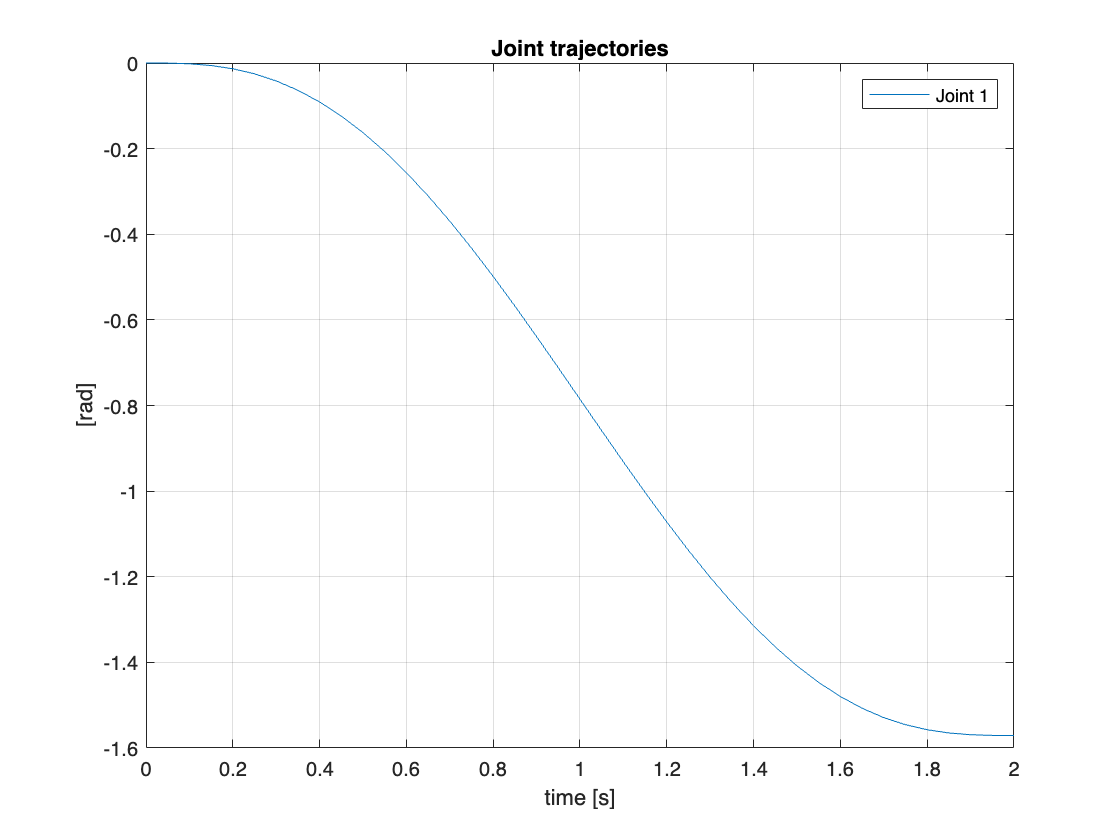

pos_1 = q_in_1 + (q_fin_1-q_in_1) * (f1 + e1*(t/T) + d1*(t/T).^2 + c1*(t/T).^3 + b1*(t/T).^4 + a1*(t/T).^5);
%pos_2 = q_in_2 + (q_fin_2-q_in_2) * (f2 + e2*(t/T) + d2*(t/T).^2 + c2*(t/T).^3 + b2*(t/T).^4 + a2*(t/T).^5);
%pos_3 = q_in_3 + (q_fin_3-q_in_3) * (f3 + e3*(t/T) + d3*(t/T).^2 + c3*(t/T).^3 + b3*(t/T).^4 + a3*(t/T).^5);

plot(t, pos_1, 'DisplayName', 'Joint 1'); hold on;
%plot(t, pos_2, 'DisplayName', 'Joint 2'); hold on;
%plot(t, pos_3, 'DisplayName', 'Joint 3'); 
title('Joint trajectories'); xlabel('time [s]'); ylabel('[rad]'); hold off; legend; grid;

#### Velocities plots

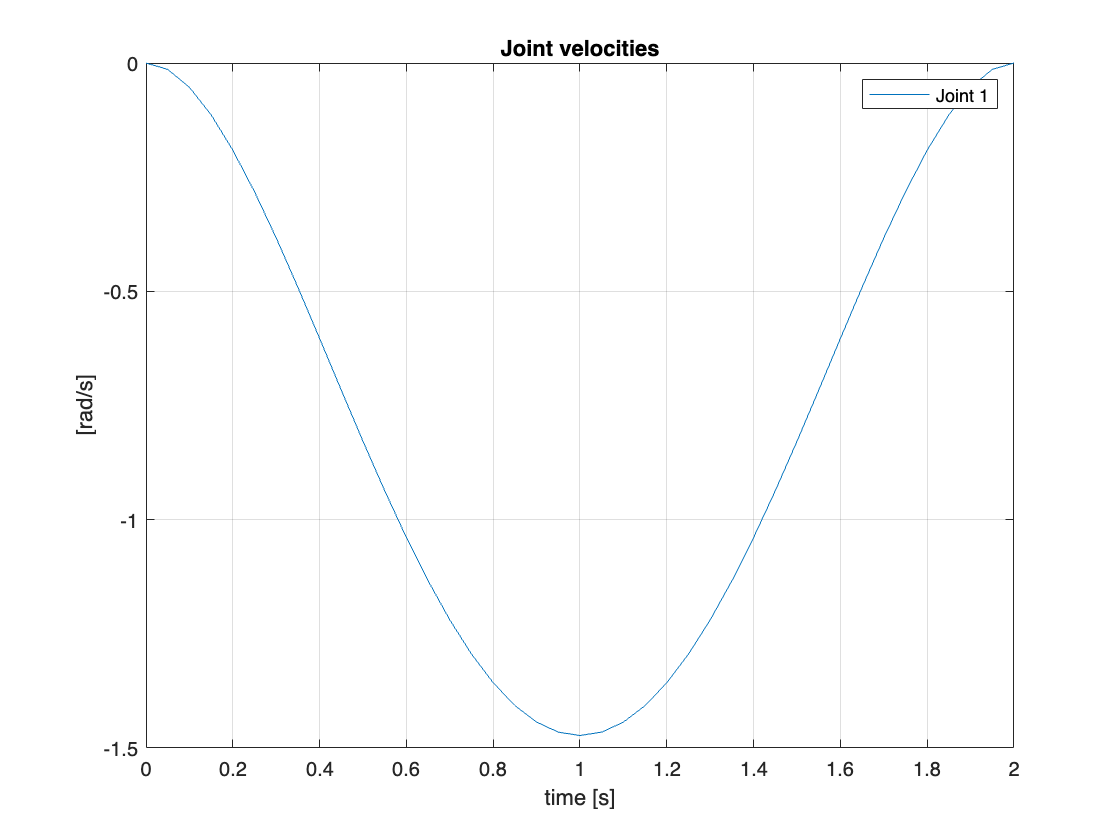

vel_1 = ((q_fin_1-q_in_1)/T) * (e1 + 2*d1*(t/T) + 3*c1*(t/T).^2 + 4*b1*(t/T).^3 + 5*a1*(t/T).^4);
%vel_2 = ((q_fin_2-q_in_2)/T) * (e2 + 2*d2*(t/T) + 3*c2*(t/T).^2 + 4*b2*(t/T).^3 + 5*a2*(t/T).^4);
%vel_3 = ((q_fin_3-q_in_3)/T) * (e3 + 2*d3*(t/T) + 3*c3*(t/T).^2 + 4*b3*(t/T).^3 + 5*a3*(t/T).^4);

plot(t, vel_1, 'DisplayName', 'Joint 1'); hold on;
%plot(t, vel_2, 'DisplayName', 'Joint 2'); hold on;
%plot(t, vel_3, 'DisplayName', 'Joint 3'); 
title('Joint velocities'); xlabel('time [s]'); ylabel('[rad/s]'); hold off; legend; grid;

#### Accelerations plots

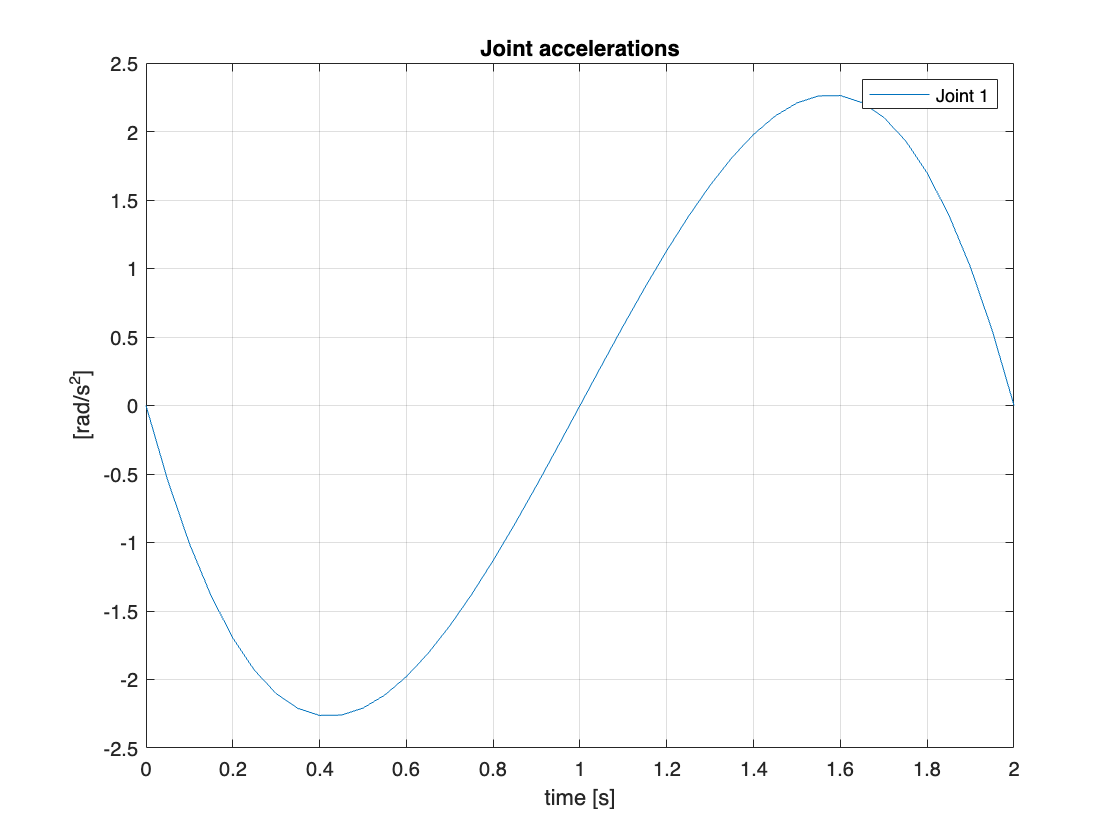

acc_1 = ((q_fin_1-q_in_1)/T^2) * (2*d1 + 6*c1*(t/T) + 12*b1*(t/T).^2 + 20*a1*(t/T).^3);
%acc_2 = ((q_fin_2-q_in_2)/T^2) * (2*d2 + 6*c2*(t/T) + 12*b2*(t/T).^2 + 20*a2*(t/T).^3);
%acc_3 = ((q_fin_3-q_in_3)/T^2) * (2*d3 + 6*c3*(t/T) + 12*b3*(t/T).^2 + 20*a3*(t/T).^3);

plot(t, acc_1, 'DisplayName', 'Joint 1'); hold on;
%plot(t, acc_2, 'DisplayName', 'Joint 2'); hold on;
%plot(t, acc_3, 'DisplayName', 'Joint 3'); 
title('Joint accelerations'); xlabel('time [s]'); ylabel('[rad/s^2]'); hold off; legend; grid;